clear;

Aufgabe 5)

1.

t = 0 : 0.1 : 6 * pi;

2.

y = exp(1i * t);

3.

realPart = real(y);
imagPart = imag(y);

%realPart = cos(t);
%imagPart = sin(t);

figure;
subplot(2,2,1);
plot(t, realPart);
xlabel("time t");
ylabel("Re\{y\}");
grid on;

subplot(2,2,2);
plot(t, imagPart);
xlabel("time t");
ylabel("Im\{y\}");
grid on;

4. y = e^(t*i) = cos(t) + i * sin(t)

5.

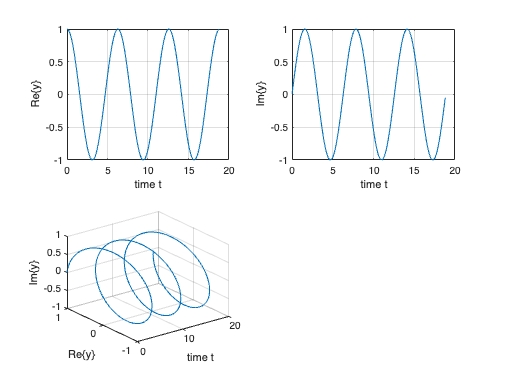

subplot(2,2,3);
plot3(t,realPart,imagPart);
grid on;
xlabel("time t");
ylabel("Re\{y\}");
zlabel("Im\{y\}");

Aufgabe 6)

x = pi/4 * [ones(1,256) 0 -1*ones(1,511) 0 ones(1,255)];

1.

Tp = 0.1;           % [s]
N = 1024;
t = 0: Tp / (N-1) :Tp;
Ts = Tp / N;        % [s]

2.

w0 = (2*pi) ./ Tp;  % [1/s]

3.

c0 = (1 ./ N) .* sum(x);
disp("c_0 = " + c0);

c_0 = 3.4694e-18


    c_0 = 0

4.

n = 0 : 1 : N - 1;
e = exp(-1 .* 1i .* 2 .* pi .* ((1 .* n) ./ N));
c1 =  (1 / N) .* sum(x .* e);
disp("c_1 = " + c1);

c_1 = 0.5+5.6812e-17i


e = exp(-1 .* 1i .* 2 .* pi .* ((-1 .* n) ./ N));
cMinus1 =  (1 / N) .* sum(x .* e);
disp("c_-1 = " + cMinus1);

c_-1 = 0.5-5.6812e-17i


c_1     = 0,5 + 0*i = 0,5

c_-1    = 0,5 - 0*i = 0,5

5.

e^(jw0t)  = cos(w0t) + j * sin(w0t)

e^(-jw0t) = cos(w0t) - j *  sin(w0t)

c_1 * e^(jw0t) + c_-1 * e^(-jw0t)

= c_1 * (cos(w0t) + j * sin(w0t)) + c_-1 * (cos(w0t) - j *  sin(w0t))

= c_1 * cos(w0t) + c_1 *  j * sin(w0t) + c_-1 * cos(w0t) - c_-1 *  j *  sin(w0t)

= cos(w0t) * (c_1 + c_-1) + j * sin(w0t) * (c_1 - c_-1)

konstCos = c1 + cMinus1;
konstSin = round(c1 - cMinus1) * 1i;
disp("sin(w0t) * " + konstSin + " + cos(w0t) * " + konstCos);

sin(w0t) * 0 + cos(w0t) * 1


6.

m = -511:1:511;
cm = zeros(1, length(m));
for i = 1 : length(m)
    e = exp(-1 .* 1i .* 2 .* pi .* ((m(i) .* n) ./ N));
    cm(1, i) = (1 ./ N) .* sum(x .* e);
    disp("c_" + m(i) + " = " + cm(1, i));
end

c_-511 = -4.7062e-06-5.7952e-15i
c_-510 = 7.0788e-16-5.7905e-16i
c_-509 = 1.4119e-05-3.3502e-17i
c_-508 = -3.0228e-16-1.1771e-15i
c_-507 = -2.3533e-05-2.0134e-16i
c_-506 = -7.1991e-17+4.5547e-16i
c_-505 = 3.2948e-05-8.0773e-17i
c_-504 = -1.0776e-15-9.4017e-16i
c_-503 = -4.2367e-05+8.164e-17i
c_-502 = -4.5656e-16-7.4879e-16i
c_-501 = 5.1788e-05+9.8977e-16i
c_-500 = -9.8662e-18-2.4252e-17i
c_-499 = -6.1213e-05+3.6954e-15i
c_-498 = 5.1391e-17+3.9641e-17i
c_-497 = 7.0643e-05-1.5287e-16i
c_-496 = -4.3043e-17+1.0619e-15i
c_-495 = -8.0078e-05-5.047e-16i
c_-494 = 2.7831e-16+5.9509e-17i
c_-493 = 8.9519e-05-1.854e-16i
c_-492 = -1.9624e-16-3.8843e-16i
c_-491 = -9.8967e-05-9.1832e-17i
c_-490 = 5.5316e-16+5.9684e-16i
c_-489 = 0.00010842+3.0954e-16i
c_-488 = 9.7632e-16-1.8039e-15i
c_-487 = -0.00011789-5.7419e-16i
c_-486 = 8.7387e-17-1.7671e-16i
c_-485 = 0.00012736-2.0513e-16i
c_-484 = 2.9805e-16+3.3271e-16i
c_-483 = -0.00013684-1.2902e-16i
c_-482 = 7.3184e-17-7.0329e-16i
c_-481 = 0.00014633+2.1847e-

7.

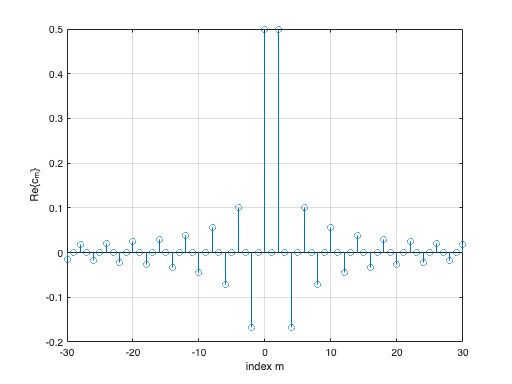

index = (511-30):1:(511+30);
xValues = -30:1:30;
cmReal = real(cm(index));

figure;
stem(xValues, cmReal);
xlabel("index m");
ylabel("Re\{c_m\}");
grid on;

8. Das Singnal hat für alle m = gerade keine Realteil.

9.

x2 = zeros(1, N);
for i = 1:length(t)
    e = exp(1i .* m .* w0 .* t(i));
    x2(1, i) = sum(cm .* e);
end

10.

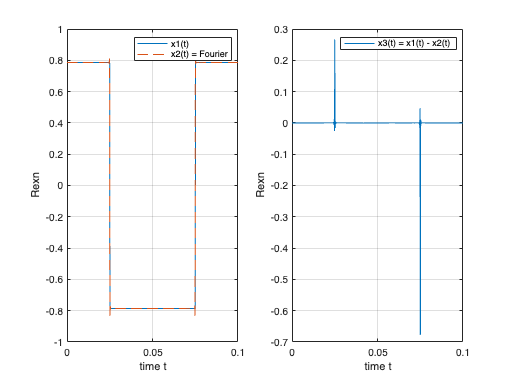

figure;
xDiff = (x - x2);
subplot(1,2,1);
plot(t, real(x), t, real(x2), "--");
xlabel("time t");
ylabel("Re{xn}");
legend("x1(t)", "x2(t) = Fourier");

subplot(1,2,2);
plot(t, real(xDiff));
xlabel("time t");
ylabel("Re{xn}");
legend("x3(t) = x1(t) - x2(t)");
grid on;

subplot(1,2,1)
xlim([0.000 0.100]);
ylim([-1.00 1.00]);
grid on;

11.

maxError = 0;
if round(abs(min(xDiff)),6) >= round(max(xDiff),6)
    maxError = round(min(real(xDiff)), 6);
else
    maxError = round(max(real(xDiff)), 6);
end
disp("Der Betrag des maximalen Fehlers ist: " + abs(maxError));

Der Betrag des maximalen Fehlers ist: 0.67681


12.

t2 = 0 : Tp / 8191 : Tp;

13.

x3 = zeros(1, length(t2));
for i = 1: length(t2)
    e = exp(1i .* m .* w0 .* t2(i));
    x3(1, i) = sum(cm .* e);
end

14.

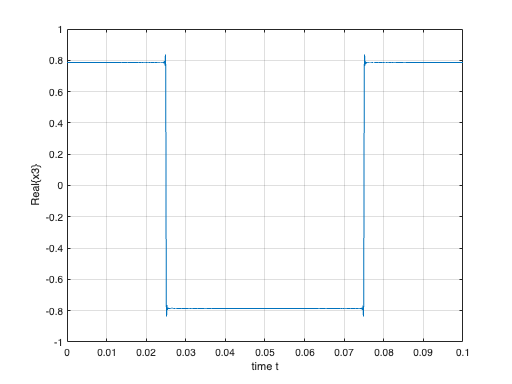

figure;
plot(t2, real(x3));
xlabel("time t");
ylabel("Real\{x3\}");
grid on;

disp(max(real(x2)));

    0.8109



disp(max(real(x3)));

    0.8368



disp(min(real(x2)));

   -0.8322



disp(min(real(x3)));

   -0.8368



An den Sprungstellen größere Überschwinger, Signal mit gleichen Koeffizienten, aber feinerer Abtastung -> Gibbsches Phänomen